task = 'contrDetectBadpt';
% task = 'contrLocalBadpt';
folder = '/Volumes/CONSENPHAS-Q5078';
% folder = 'Z:/';
folder = '/Users/henry/Documents/local-data';

% load behavioural data table
file = fullfile(folder,task,'derivatives','eeg','ic','compiled-data-struct.mat');
load(file, 'df')
df = struct2table(df);

pids = unique(df.pid); 
for n = 1:numel(pids)
    ix = df.pid == pids(n); 
    contr = df.contrast(ix); 
    contr = contr(contr > 0 & contr < 1);
    thr = 10.^mean(log10(contr));
    df.ratio_contr(ix) = df.contrast(ix) ./ thr;
end

df.y = df.accuracy;
df.phi = -abs(circ_dist(df.phi_echt, df.phase_offset));

df.x = df.ratio_contr; 
df.x1 = df.ratio_contr.^2;
df.x2 = df.ratio_contr.^.5;

m0 = fitglme(df, 'y~(x+x1+x2) + (1|pid)','distribution','binomial','fitmethod','laplace')

m0 = Generalized linear mixed-effects model fit by ML

Model information:
    Number of observations           29090
    Fixed effects coefficients           4
    Random effects coefficients         32
    Covariance parameters                1
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       Laplace

Formula:
    y ~ 1 + x + x1 + x2 + (1 | pid)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    28858    28899    -14424           28848   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF       pValue         Lower      Upper  
    {'(Intercept)'}        -2.7741     0.090084    -30.794    29086    6.1779e-205    -2.9506    -2.5975
    {'x'          }         15.642      0.36717     42.601    29086              0     14.922     16.361
    {'x1'         

anova(m0)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2      pValue     
    {'(Intercept)'}        948.27    1      29086    6.1779e-205
    {'x'          }        1814.9    1      29086              0
    {'x1'         }         906.9    1      29086    3.2043e-196
    {'x2'         }        1071.2    1      29086    9.4575e-231


m1 = fitglme(df, 'y~(x+x1+x2)*amp_echt + (1|pid)','distribution','binomial','fitmethod','laplace')

m1 = Generalized linear mixed-effects model fit by ML

Model information:
    Number of observations           24391
    Fixed effects coefficients           8
    Random effects coefficients         32
    Covariance parameters                1
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       Laplace

Formula:
    y ~ 1 + amp_echt*x + amp_echt*x1 + amp_echt*x2 + (1 | pid)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    24175    24248    -12078           24157   

Fixed effects coefficients (95% CIs):
    Name                   Estimate       SE           tStat       DF       pValue         Lower         Upper    
    {'(Intercept)'}            -2.8037      0.12682     -22.109    24383    2.9501e-107       -3.0523      -2.5552
    {'amp_echt'   }        -0.00087274    0.0039481    -0.22105    24383    

anova(m1)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat       DF1    DF2      pValue     
    {'(Intercept)'}           488.8    1      24383    2.9501e-107
    {'amp_echt'   }        0.048864    1      24383        0.82505
    {'x'          }          800.97    1      24383    2.1051e-173
    {'x1'         }          378.92    1      24383     9.2345e-84
    {'x2'         }          477.85    1      24383    6.4027e-105
    {'amp_echt:x' }          3.3532    1      24383       0.067088
    {'amp_echt:x1'}          1.6473    1      24383        0.19934
    {'amp_echt:x2'}          2.6889    1      24383        0.10107


compare(m0,m1)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue
    m0       5     28858    28899    -14424                               
    m1       9     24175    24248    -12078    4690.9    4          0     


m2 = fitglme(df, 'y~(x+x1+x2)*phi + (1|pid)','distribution','binomial','fitmethod','laplace')

m2 = Generalized linear mixed-effects model fit by ML

Model information:
    Number of observations           24391
    Fixed effects coefficients           8
    Random effects coefficients         32
    Covariance parameters                1
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       Laplace

Formula:
    y ~ 1 + phi*x + phi*x1 + phi*x2 + (1 | pid)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    24185    24258    -12084           24167   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF       pValue        Lower        Upper   
    {'(Intercept)'}          -3.009     0.17601    -17.096    24383    3.8269e-65       -3.354     -2.6641
    {'phi'        }        -0.11481    0.086822    -1.3224    24383       0.18606     -0.28499    0.055366


anova(m2)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2      pValue    
    {'(Intercept)'}        292.27    1      24383    3.8269e-65
    {'phi'        }        1.7486    1      24383       0.18606
    {'x'          }        304.55    1      24383    8.7024e-68
    {'x1'         }        144.99    1      24383    2.6894e-33
    {'x2'         }        160.36    1      24383    1.2299e-36
    {'phi:x'      }        4.4838    1      24383      0.034227
    {'phi:x1'     }        3.1263    1      24383       0.07705
    {'phi:x2'     }        4.8766    1      24383      0.027232


compare(m0,m2)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue
    m0       5     28858    28899    -14424                               
    m2       9     24185    24258    -12084    4680.5    4          0     


m3 = fitglme(df, 'y~(x+x1+x2)*phi*amp_echt + (1|pid)','distribution','binomial','fitmethod','laplace')

m3 = Generalized linear mixed-effects model fit by ML

Model information:
    Number of observations           24391
    Fixed effects coefficients          16
    Random effects coefficients         32
    Covariance parameters                1
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       Laplace

Formula:
    y ~ 1 + amp_echt*phi + amp_echt*x + phi*x + amp_echt*x1 + phi*x1 + amp_echt*x2 + phi*x2 + amp_echt:phi:x + amp_echt:phi:x1 + amp_echt:phi:x2 + (1 | pid)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    24180    24318    -12073           24146   

Fixed effects coefficients (95% CIs):
    Name                       Estimate      SE           tStat       DF       pValue        Lower         Upper    
    {'(Intercept)'    }           -2.8671      0.24959     -11.487    24375    1.8299e-30      

anova(m3)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                       FStat       DF1    DF2      pValue    
    {'(Intercept)'    }          131.96    1      24375    1.8299e-30
    {'amp_echt'       }         0.62603    1      24375       0.42882
    {'phi'            }         0.13079    1      24375       0.71762
    {'x'              }          167.54    1      24375    3.4006e-38
    {'x1'             }          68.444    1      24375    1.3716e-16
    {'x2'             }          97.058    1      24375    7.4291e-23
    {'amp_echt:phi'   }         0.63874    1      24375       0.42418
    {'amp_echt:x'     }          1.9189    1      24375       0.16599
    {'phi:x'          }          1.4403    1      24375       0.23011
    {'amp_echt:x1'    }         0.36226    1      24375       0.54726
    {'phi:x1'         }          1.7471    1      24375       0.18625
    {'amp_echt:x2'    }          2.3482    1      24375       0.12544
    {'phi:x2'     

compare(m2,m3)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue   
    m2        9    24185    24258    -12084                                  
    m3       17    24180    24318    -12073    20.789    8          0.0077298


## compute AIC weights

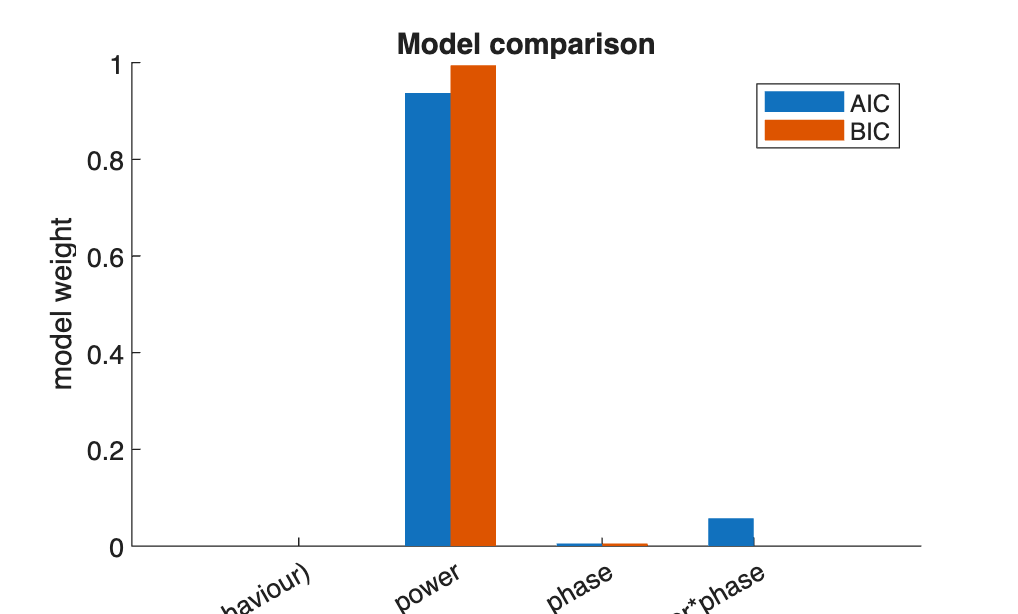

Ms = {m0, m1, m2, m3}; 

aics = nan(1,  numel(Ms)); 
bics = aics;
liks = aics;
for n = 1:numel(aics)
    aics(n) = Ms{n}.ModelCriterion.AIC;
    bics(n) = Ms{n}.ModelCriterion.BIC;
    liks(n) = Ms{n}.LogLikelihood;
end
aic_change = aics - min(aics);
bic_change = bics - min(bics);

aicw = exp(-.5*aic_change); 
aicw = aicw ./ sum(aicw);

bicw = exp(-.5*bic_change);
bicw = bicw ./ sum(bicw);

bw = .3; 
jit = .15; 
clf
nexttile
hold on 
bar((1:numel(Ms))-jit, aicw, bw, 'edgecolor','none')
bar((1:numel(Ms))+jit, bicw, bw, 'edgecolor','none')
xticks(1:numel(Ms))
xticklabels({'null (behaviour)','power','phase','power*phase'})
ylabel('model weight')
legend({'AIC','BIC'})
title('Model comparison')


save(fullfile(folder,task,'plot-data','log-reg-IC.mat'), 'aics','bics','aicw','bicw','liks')

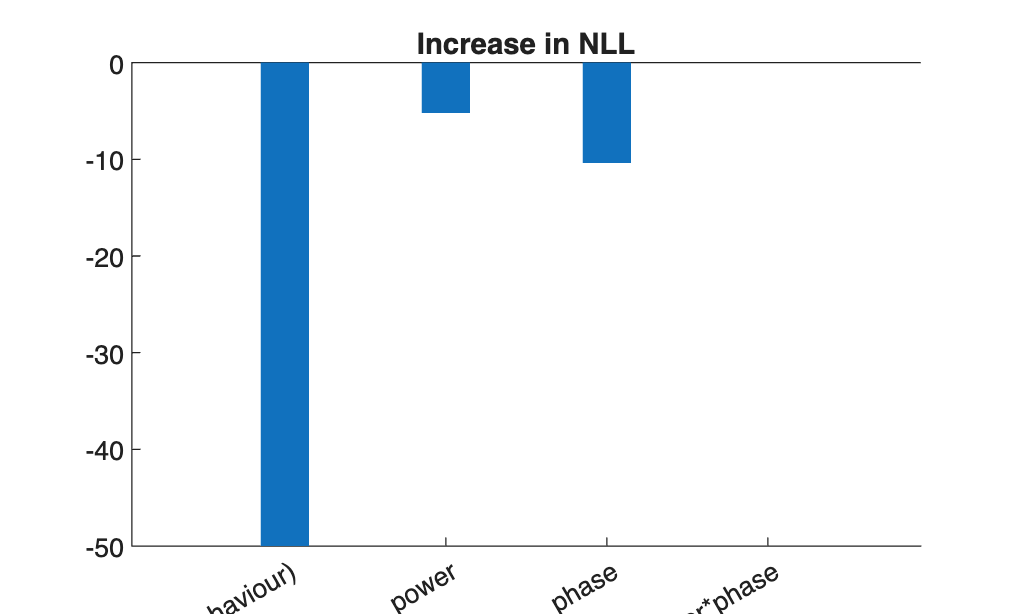

% differences from null (behaviour only) model
clf
nexttile
hold on 
bar((1:numel(Ms)), (liks-max(liks)), bw, 'edgecolor','none')
% bar((1:numel(Ms))+jit, bics-bics(1), bw, 'edgecolor','none')
xticks(1:numel(Ms))
xticklabels({'null (behaviour)','power','phase','power*phase'})

ylim([-50,0])
% ylabel('model weight')
% legend({'LogLik'})
title('Increase in NLL')